syms t;
syms theta_1(t) theta_2(t) theta_3(t);
syms m1 m2 m3 I1 I2 I3;
syms l1 l2 l3 d1 d2 d3;
syms g;

%Geometry and dimensions
m1 = subs(m1,m1,1);
m2 = subs(m2,m2,1);
m3 = subs(m3,m3,1);

%l0 = subs(l0,l0,0);
l1 = subs(l1,l1,0.5);
l2 = subs(l2,l2,0.5);
l3 = subs(l3,l3,0.50);

I1 = subs(I1,I1,(1/12)*m1*l1*l1);
I2 = subs(I2,I2,(1/12)*m2*l2*l2);
I3 = subs(I3,I3,(1/12)*m3*l3*l3);

d1 = subs(d1,d1,0.5*l1);
d2 = subs(d2,d2,0.5*l2);
d3 = subs(d3,d3,0.5*l3);
g = subs(g,g,9.8);

g_f = [0;-g;0];
theta_dot = diff(theta_1(t),t);
theta2_dot = diff(theta_2(t),t);
theta3_dot = diff(theta_3(t),t);
theta_dot_dot = diff(theta_dot,t);
theta2_dot_dot = diff(theta2_dot,t);
theta3_dot_dot = diff(theta3_dot,t);

q = [theta_1(t);theta_2(t);theta_3(t)];
q_dot = [theta_dot;theta2_dot;theta3_dot];
q_dot_dot = [theta_dot_dot;theta2_dot_dot;theta3_dot_dot];

%Constant matrices
Id = eye(3);
Id_1 = eye(6);
ZO = zeros(3,3);
ZO_1 = zeros(6,6);
ZO_c = zeros(6,1);
ZO_c2 = zeros(3,1);

%System Parameters
e1 = [0;0;1];
e2 = [0;0;1];
e3 = [0;0;1];

d1_vec = formula([d1*cos(theta_1);d1*sin(theta_1);0]);
d2_vec = formula([d2*cos(theta_1+theta_2);d2*sin(theta_1+theta_2);0]);
d3_vec = formula([d3*cos(theta_1+theta_2+theta_3);d3*sin(theta_1+theta_2+theta_3);0]);
r1 = formula([(l1-d1)*cos(theta_1);(l1-d1)*sin(theta_1);0]);
r2 = formula([(l2-d2)*cos(theta_1+theta_2);(l2-d2)*sin(theta_1+theta_2);0]);

ang1 = formula(diff([0;0;theta_1],t));
ang2 = formula(diff([0;0;theta_1+theta_2],t));
ang3 = formula(diff([0;0;theta_1+theta_2+theta_3],t));

p1 = [e1;cross(e1,d1_vec)];
p2 = [e2;cross(e2,d2_vec)];
p3 = [e3;cross(e3,d3_vec)];
B21 = [Id ZO;vec_cross(-r1-d2_vec) Id];
B32 = [Id ZO;vec_cross(-r2-d3_vec) Id];
B31 = B32*B21;
B = [ZO_1 ZO_1 ZO_1;B21 ZO_1 ZO_1;ZO_1 B32 ZO_1];

%DeNOC Matrices
Nd = [p1 ZO_c ZO_c;ZO_c p2 ZO_c;ZO_c ZO_c p3];
Nl = [Id_1 ZO_1 ZO_1;B21 Id_1 ZO_1;B31 B32 Id_1];

I_1 = [0 0 0;0 0 0;0 0 I1];
I_2 = [0 0 0;0 0 0;0 0 I2];
I_3 = [0 0 0;0 0 0;0 0 I3];
M1 = [I_1 ZO;ZO m1*Id];
M2 = [I_2 ZO;ZO m2*Id];
M3 = [I_2 ZO;ZO m3*Id];
M = [M1 ZO_1 ZO_1;ZO_1 M2 ZO_1;ZO_1 ZO_1 M3];

W1 = [vec_cross(ang1) ZO;ZO ZO];
W2 = [vec_cross(ang2) ZO;ZO ZO];
W3 = [vec_cross(ang3) ZO;ZO ZO];
W = [W1 ZO_1 ZO_1;ZO_1 W2 ZO_1;ZO_1 ZO_1 W3];

q_dd = [diff(theta_1,t,2);diff(theta_2,t,2);diff(theta_3,t,2)];
q_d = [diff(theta_1,t);diff(theta_2,t);diff(theta_3,t)];

N = Nl*Nd;
N_d = diff(N,t);

%External Wrench
W1_e = [ZO_c2;m1*g_f];
W2_e = [ZO_c2;m2*g_f];
W3_e = [ZO_c2;m3*g_f];
W_e = [W1_e;W2_e;W3_e];

eqn = (M*N*q_dd)+(M*N_d*q_d)+(W*M*N*q_d)-W_e;
final_eqn = formula(transpose(N)*eqn);

eqn_theta1 = final_eqn(1);
eqn_theta2 = final_eqn(2);
eqn_theta3 = final_eqn(3);

%Constructing matrices
syms a b c;
eqn_theta1 = subs(eqn_theta1,[diff(theta_dot,t),diff(theta2_dot,t),diff(theta3_dot,t)],[a,b,c]);
eqn_theta2 = subs(eqn_theta2,[diff(theta_dot,t),diff(theta2_dot,t),diff(theta3_dot,t)],[a,b,c]);
eqn_theta3 = subs(eqn_theta3,[diff(theta_dot,t),diff(theta2_dot,t),diff(theta3_dot,t)],[a,b,c]);

M1 = simplify(formula([(diff(eqn_theta1,a)) (diff(eqn_theta1,b)) (diff(eqn_theta1,c))]));
M2 = simplify(formula([(diff(eqn_theta2,a)) (diff(eqn_theta2,b)) (diff(eqn_theta2,c))]));
M3 = simplify(formula([(diff(eqn_theta3,a)) (diff(eqn_theta3,b)) (diff(eqn_theta3,c))]));
M = [M1;M2;M3];

C_matrix = zeros(3,3);
C_matrix = symmatrix(C_matrix);
C_matrix = symmatrix2sym(C_matrix);

for i=1:3
    for j=1:3
        for k=1:3
            temp = simplify(formula(0.5*((diff(M(i,j),q(k,1))) + ( ...
                diff(M(i,k),q(j,1))) - (diff(M(k,j),q(i,1))))*q_dot(k,1)));
            C_matrix(i,j) = C_matrix(i,j) + temp;
        end
    end
end

G_matrix = simplify(final_eqn-(M*q_dot_dot)-(C_matrix*q_dot));


%Inverse Dynamics problem

tbeg = 0;
tend2 = 2;
dt2 = 0.01;

thinit2 = pi/6;
th2nit2 = pi/6;
th3nit2 = pi/8;

tau1 = zeros(size(tbeg:dt2:tend2,2),1);
tau2 = zeros(size(tbeg:dt2:tend2,2),1);
tau3 = zeros(size(tbeg:dt2:tend2,2),1);
i = 1;
th1 = thinit2;
th2 = th2nit2;
th3 = th3nit2;
w1 = 1;
w2 = 1;
w3 = 1;
for tim = tbeg:dt2:tend2
        M_ode = double(subs(M,transpose(q),[th1,th2,th3]));

        C_ode1 = subs(C_matrix,transpose(q_dot),[w1,w2,w3]);
        C_ode = double(subs(C_ode1,transpose(q),[th1,th2,th3]));

        G_ode = double(subs(G_matrix,transpose(q),[th1,th2,th3]));
        tau1(i,1) = (M_ode(1,:)*[0;0;0]) + (C_ode(1,:)*[w1;w2;w3]) + (G_ode(1,1));
        tau2(i,1) = (M_ode(2,:)*[0;0;0]) + (C_ode(2,:)*[w1;w2;w3]) + (G_ode(2,1));
        tau3(i,1) = (M_ode(3,:)*[0;0;0]) + (C_ode(3,:)*[w1;w2;w3]) + (G_ode(3,1));
        th1 = th1 + (w1*dt2);
        th2 = th2 + (w2*dt2);
        th3 = th3 + (w3*dt2);
        i = i+1;
end

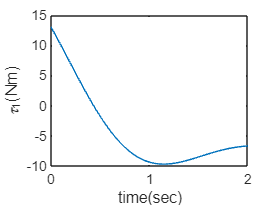

tot_time = transpose(tbeg:dt2:tend2);
plot(tot_time,tau1)
xlabel('time(sec)') 
ylabel('\tau_1(Nm)')

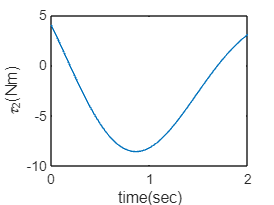

plot(tot_time,tau2)
xlabel('time(sec)') 
ylabel('\tau_2(Nm)')

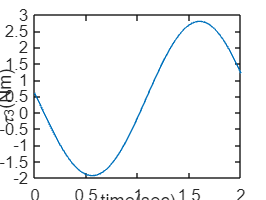

plot(tot_time,tau3)
xlabel('time(sec)') 
ylabel('\tau_3(Nm)')

%Using all the information to derive equations using ODE-45

tstart = 0;
tend = 2;
dt = 0.01;
n = 20;

%[thinit,phinit,psinit] = FourB_IK(0);

%Initial conditions
thinit = pi/6;
th2nit = pi/6;
th3nit = pi/8;

xinit = [thinit th2nit th3nit 0 0 0];

X_final = zeros(1,6);
tspan2 = zeros(1,1);

for ti = tstart:dt:tend-dt
    M_ode = double(subs(M,transpose(q),(xinit(1:3))));

    C_ode1 = subs(C_matrix,transpose(q_dot),(xinit(4:6)));
    C_ode = double(subs(C_ode1,transpose(q),(xinit(1:3))));

    G_ode = double(subs(G_matrix,transpose(q),(xinit(1:3))));

    %Torques
   %tau = [0;0;-0.2];
    
%     constr_ode = double(subs(psi_Matrix,transpose(q),(xinit(1:2))));
% 
%     constr_d_ode_1 = subs(psi_Matrix_dot,transpose(q_dot),(xinit(3:4)));
%     constr_dot_ode = double(subs(constr_d_ode_1,transpose(q),(xinit(1:2))));

    tspan = [ti ti+dt];
    [time,x_ode] = ode45(@(time,x_ode)R3dynamicsIntegratingFunc(time,x_ode,(M_ode),(C_ode),(G_ode)), tspan, xinit);
    xinit = x_ode(size(x_ode,1),:);
    X_final = [X_final;x_ode(size(x_ode,1),:)];
    tspan2 = [tspan2;ti+dt];
end


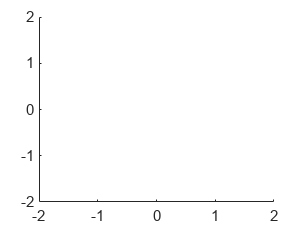

%%
clc
close all

%hold on
pt1 = [l1*cos(X_final(2,1)),l1*sin(X_final(2,1))];
pt2 = [(l1*cos(X_final(2,1))) + (l2*cos(X_final(2,1)+X_final(2,2))),(l1*sin(X_final(2,1))) + (l2*sin(X_final(2,1)+X_final(2,2)))];
pt3 = [pt2(1) + (l3*cos(X_final(2,1)+X_final(2,2)+X_final(2,3))),pt2(2) + (l3*sin(X_final(2,1)+X_final(2,2)+X_final(2,3)))];
% plot([0 pt1(1)],[0 pt1(2)])
% plot([pt1(1) pt2(1)],[pt1(2) pt2(2)])
% plot([l0 pt3(1)],[0 pt3(2)])

filename = 'animation.gif';

% X = [0 pt1(1) pt2(1) ];
% Y = [0 pt1(2) pt2(2)];
% X2 = [l0 pt3(1)];
% Y2 = [0 pt3(2)];
X = [0 pt1(1) pt2(1) pt3(1) ];
Y = [0 pt1(2) pt2(2) pt3(2) ];
xlim([-2, 2]); 
ylim([-2, 2]); 

f = figure('Name', 'Sinusoid', 'MenuBar', 'none', 'NumberTitle', 'off'); 
p = plot(X, Y, '-b'); 
%p2 = plot([0 pt3(1)],[0 pt3(2)]);
for n = 2:length(tspan2)
    
pt1 = [l1*cos(X_final(n,1)),l1*sin(X_final(n,1))];
pt2 = [(l1*cos(X_final(n,1))) + (l2*cos(X_final(n,1)+X_final(n,2))),(l1*sin(X_final(n,1))) + (l2*sin(X_final(n,1)+X_final(n,2)))];
pt3 = [pt2(1) + (l3*cos(X_final(n,1)+X_final(n,2)+X_final(n,3))),pt2(2) + (l3*sin(X_final(n,1)+X_final(n,2)+X_final(n,3)))];
% X = [0 pt1(1) pt2(1) ];
% Y = [0 pt1(2) pt2(2)];
% X2 = [l0 pt3(1)];
% Y2 = [0 pt3(2)];
X = [0 pt1(1) pt2(1) pt3(1) ];
Y = [0 pt1(2) pt2(2) pt3(2) ];
xlim([-2, 2]); 
ylim([-2, 2]); 
 set(p, 'YData', Y , 'Xdata',X); 
 %set(p2,'YData',[0 pt3(2)],'Xdata',[0 pt3(1)]);
 pause(0.05); 

     % Saving the figure
    frame = getframe(gcf);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    if n == 2
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf,...
        'DelayTime',0.1);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append',...
        'DelayTime',0.1);
    end

end 
delete(f);


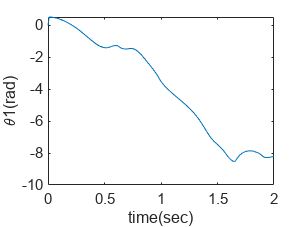

%Plot for theta 1
figure(1)

plot(tspan2,X_final(:,1));
xlabel('time(sec)') 
ylabel('\theta1(rad)')

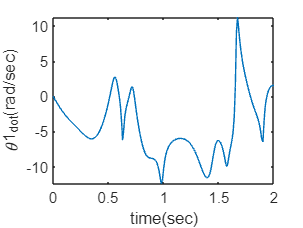

figure(2)

plot(tspan2,X_final(:,4)); %theta_dot
xlabel('time(sec)') 
ylabel('\theta1_{dot}(rad/sec)')

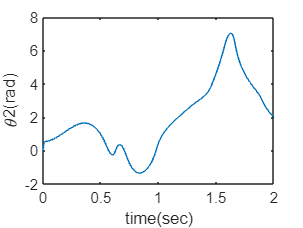


%Plot for theta 2
figure(3)
plot(tspan2,X_final(:,2));
xlabel('time(sec)') 
ylabel('\theta2(rad)')

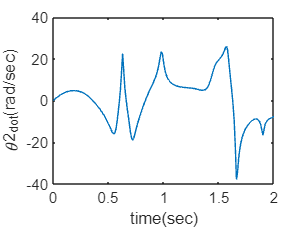

figure(4)
plot(tspan2,X_final(:,5));  %phi_dot
xlabel('time(sec)') 
ylabel('\theta2_{dot}(rad/sec)')

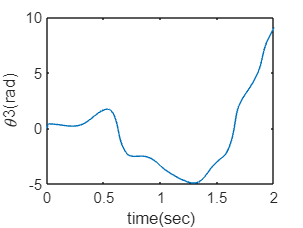


%Plot for theta 3
figure(5)

plot(tspan2,X_final(:,3));
xlabel('time(sec)') 
ylabel('\theta3(rad)')

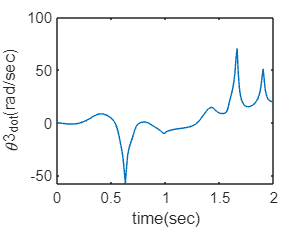

figure(6)

plot(tspan2,X_final(:,6));      %psi_dot
xlabel('time(sec)') 
ylabel('\theta3_{dot}(rad/sec)')

function dxdt = R3dynamicsIntegratingFunc(time,x,mass,coriolis,gravity)
    
    M_ode = mass;
    C_ode = coriolis;
    G_ode = gravity;
%     constr_ode = constraint;
%     constr_dot_ode = constraint_dot;

    f = (-C_ode*x(4:6)) - G_ode ;
%     T1 = constr_ode*(M_ode\transpose(constr_ode));
%     T2 = (constr_ode*(M_ode\f))+(constr_dot_ode*x(4:6));
    dxdt(1:3) = x(4:6);
    dxdt(4:6) = M_ode\(f);
    dxdt = transpose(dxdt);

end


function cross2 = vec_cross(a)

cross2 = [0 -a(3) a(2);a(3) 0 -a(1);-a(2) a(1) 0];

end